# Problema1 - Suplimentara

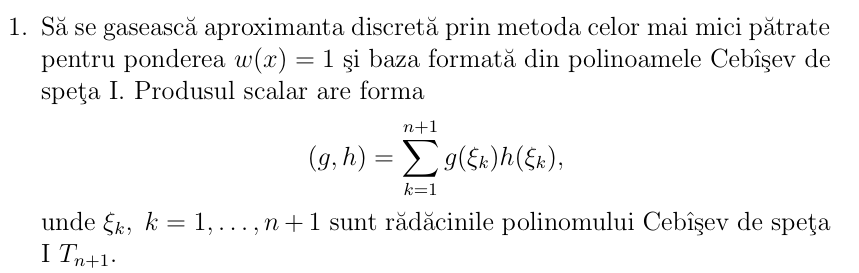

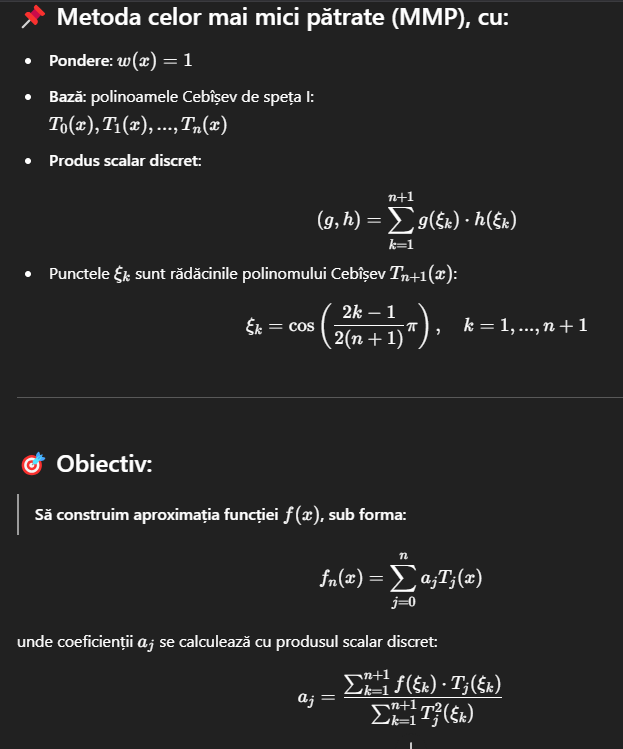

function [a, f_aprox, xx] = aproximare_cebisev_discreta(f, n)

    % 1. calc nodurile Cebisev
    k = 1:n+1;
    xk = cos((2*k - 1) * pi / (2*(n+1)));

    % 2. Evaluam functia in aceste puncte
    f_vals = f(xk);

    % 3. Construim baza polinomiala Cebisev
    T = zeros(n+1, n+1);  % T(j+1, k) = T_j(x_k)
    T(1,:) = 1;
    if n >= 1
        T(2,:) = xk;
        for j = 2:n
            T(j+1,:) = 2 * xk .* T(j,:) - T(j-1,:);
        end
    end

    % 4. Calculam coeficientii a_j prin MPP discret
    a = zeros(n+1,1);
    for j = 0:n
        num = sum(f_vals .* T(j+1,:));
        den = sum(T(j+1,:).^2);
        a(j+1) = num / den;
    end

    % 5. Evaluam aproximarea pe un domeniu [-1,1]
    xx = linspace(-1, 1, 300);
    T_eval = zeros(n+1, length(xx));
    T_eval(1,:) = 1;
    if n >= 1
        T_eval(2,:) = xx;
        for j = 2:n
            T_eval(j+1,:) = 2 * xx .* T_eval(j,:) - T_eval(j-1,:);
        end
    end
    f_aprox = a' * T_eval;  % produsul scalar


    figure;
    plot(xx, f(xx), 'b--', 'DisplayName', 'f(x)');
    hold on;
    plot(xx, f_aprox, 'r-', 'DisplayName', 'Aproximare Cebîșev');
    plot(xk, f_vals, 'ko', 'DisplayName', 'Puncte Cebîșev');
    legend show; grid on;
    title(sprintf('Aproximare MMP (Cebîșev, grad %d)', n));
end


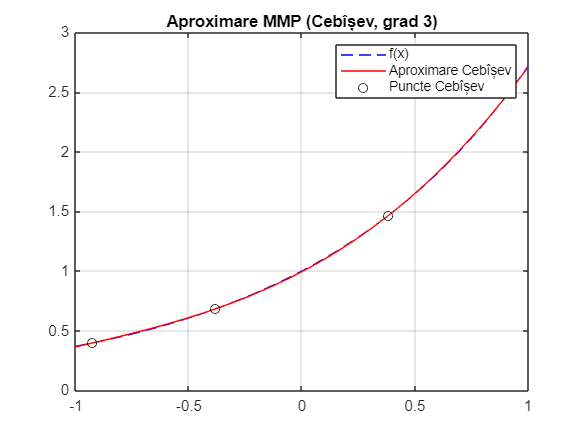

f = @(x) exp(x);   % functia de aproximat
n = 3;             % gradul aproximantului

[a, f_aprox, xx] = aproximare_cebisev_discreta(f, n);

disp('Coeficientii a_j:');

Coeficientii a_j:


disp(a);

    1.2661
    1.1303
    0.2715
    0.0438

